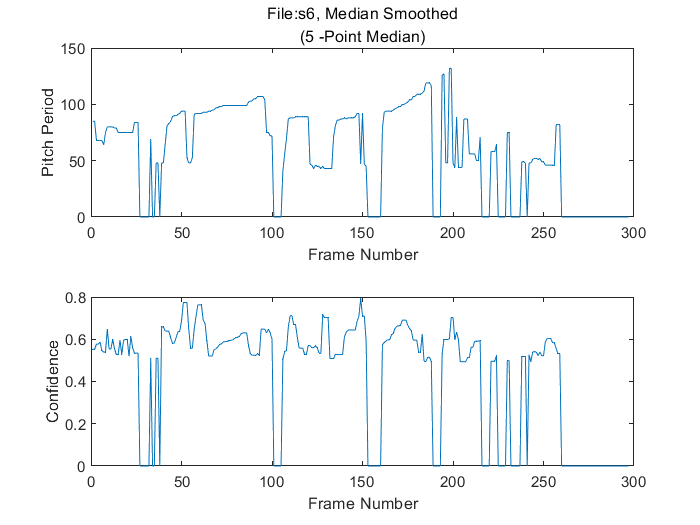

clc 
clear all 
close all 

 % 2.Audio read
[y, fs] = audioread("s6.wav"); 
 % 3.Resample
[P, Q] = rat(10e3/fs); 
y = resample(y, P, Q); fs = 10e3; 

 % 4.Deframe_matn linear filter
Wp = [100, 300] / (fs / 2); Ws = [50, 350] / (fs / 2); Rp = 3; Rs = 40; 
[~, Wn] = buttord(Wp, Ws, Rp, Rs); 
[b, a] = fir1(301, Wn); 
% freqz(b, a); 
 % 5.Linear filtering
y1 = filter(b, a, y); 
 % 6.
 % sound(y1)

 % 7.Framing
frame_length = 40 * fs / 1e3; 
frame_shift = 10 * fs / 1e3; 
window = hamming(frame_length); 
frame_mat = enframe(y1, window, frame_shift); 
frame_num = size(frame_mat, 1); 

 % 8.cepstrum
nfft = 4e3; 
[frame_fft, frame_mag, frame_phase, frame_log] = deal(zeros(frame_num, nfft)); 
[frame_ceps] = deal(zeros(frame_num, nfft)); 
for i = 1:1:frame_num 
    s1 = frame_mat(i, :); 
    frame_fft(i, :) = fft(s1, nfft); 
    frame_mag(i, :) = abs(frame_fft(i, :)); 
    frame_phase(i, :) = unwrap(angle(frame_fft(i, :))); 
    frame_log(i, :) = log(frame_mag(i, :)); 
%     frame_ceps(i,:) = real(ifft(frame_log(i,:) + 1i.*frame_phase(i,:), nfft));
    frame_ceps(i, :) = real(ifft(frame_fft(i, :), nfft)); 
end 
frame_ceps(isnan(frame_ceps)) = 0; 

 % 9.
frame_ceps1 = reshape(frame_ceps, [size(frame_ceps, 1) * size(frame_ceps, 2), 1]); 
% figure();
% index_start = 101; index_num = 20; index_end = index_start + index_num - 1;
% strips(frame_ceps1(frame_length*index_start:frame_length*index_end), frame_length);

 % 10.
nlow = 40; nhigh = 167; cut_rat = 0.9; interval = 13; median_p = 5; 

frame_ceps2 = transpose(frame_ceps); 
[p1_x, p1_y, p2_x, p2_y] = deal(zeros(frame_num,1));
[~, p1_x(:)] = max(frame_ceps2(:,:)); 
for i = 1:frame_num
    p1_y(i) = frame_ceps2(p1_x(i),i);
end

for i = 1:frame_num 
    x = p1_x(i); 
    if x <= round(interval/2) 
        frame_ceps2(1:x+round(interval/2), i) = 0; 
    elseif x > size(frame_ceps2, 1) - round(interval/2) 
        frame_ceps2(x-round(interval/2):end, i) = 0; 
    else 
        frame_ceps2(x-round(interval/2):x+round(interval/2), i) = 0; 
    end 
end 

[~, p2_x(:, 1)] = max(frame_ceps2(:, :)); 
for i = 1:frame_num
    p2_y(i) = frame_ceps2(p2_x(i),i);
end

pitch_period_tmp = abs(p1_x - p2_x); 
confidence_tmp = p1_y ./ p2_y; 
confidence_tmp(isnan(confidence_tmp)) = 0; 
confidence_tmp = confidence_tmp ./ max(confidence_tmp); 

index_low = find(pitch_period_tmp <= nlow); 
index_high = find(pitch_period_tmp >= nhigh); 
index_rat = find(confidence_tmp > cut_rat); 
index_del = unique([index_low; index_high; index_rat]); 
index_del = reshape(index_del, [length(index_del), 1]); 

pitch_period_tmp(index_del) = 0; 
confidence_tmp(index_del) = 0; 

pitch_period = median_smoother(pitch_period_tmp, median_p); 
confidence = median_smoother(confidence_tmp, median_p); 

figure; 
subplot(211); 
plot(1:frame_num, pitch_period); 
xlabel("Frame Number"), ylabel("Pitch Period"); 
title("File:s6, Median Smoothed" +newline+"(" +median_p + " -Point Median)"); 
subplot(212); 
plot(1:frame_num, confidence); 
xlabel("Frame Number"), ylabel("Confidence"); 